# **Recurrent Neural Network with Matlab**

# Create Word Embedding Layer

Create a word embedding layer with embedding dimension 300 and 5000 words.

layer = wordEmbeddingLayer(300,5000)

Include a word embedding layer in an LSTM network.

inputSize = 1;
embeddingDimension = 300;
numWords = 5000;
numHiddenUnits = 200;
numClasses = 10;

layers = [
    sequenceInputLayer(inputSize)
    wordEmbeddingLayer(embeddingDimension,numWords)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

# Initialize Word Embedding Layer with Pretrained Word Embedding

To initialize a word embedding layer in a deep learning network with the weights from a pretrained word embedding, use the `word2vec` function to extract the layer weights and set the `'Weights'` name-value pair of the `wordEmbeddingLayer` function. The word embedding layer expects columns of word vectors, so you must transpose the output of the `word2vec` function.

emb = fastTextWordEmbedding;

words = emb.Vocabulary;
dimension = emb.Dimension;
numWords = numel(words);

layer = wordEmbeddingLayer(dimension,numWords,...
    'Weights',word2vec(emb,words)')

To create the corresponding word encoding from the word embedding, input the word embedding vocabulary to the `wordEncoding` function as a list of words.

enc = wordEncoding(words)

# Create GRU Layer

Create a GRU layer with the name `'gru1'` and 100 hidden units.

layer = gruLayer(100,'Name','gru1')

Include a GRU layer in a `Layer` array.

inputSize = 12;
numHiddenUnits = 100;
numClasses = 9;

layers = [ ...
    sequenceInputLayer(inputSize)
    gruLayer(numHiddenUnits)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

# Create LSTM Layer

Create an LSTM layer with the name `'lstm1'` and 100 hidden units.

layer = lstmLayer(100,'Name','lstm1')

Include an LSTM layer in a `Layer` array.

inputSize = 12;
numHiddenUnits = 100;
numClasses = 9;

layers = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

# Train Network for Sequence Classification

Train a deep learning LSTM network for sequence-to-label classification.

Load the Japanese Vowels data set as described in [1] and [2]. `XTrain` is a cell array containing 270 sequences of varying length with 12 features corresponding to LPC cepstrum coefficients. `Y` is a categorical vector of labels 1,2,...,9. The entries in `XTrain` are matrices with 12 rows (one row for each feature) and a varying number of columns (one column for each time step).

[XTrain,YTrain] = japaneseVowelsTrainData;

 Visualize the first time series in a plot. Each line corresponds to a feature.

figure
plot(XTrain{1}')
title("Training Observation 1")
numFeatures = size(XTrain{1},1);
legend("Feature " + string(1:numFeatures),'Location','northeastoutside')

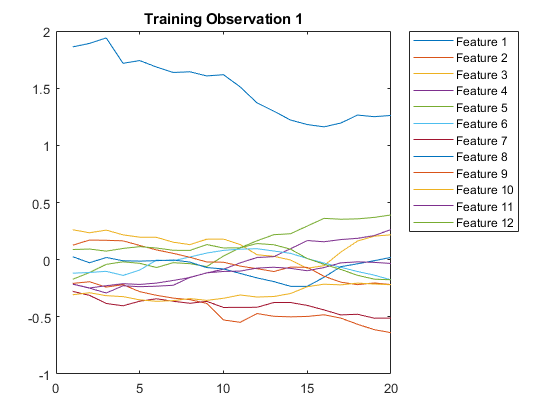

Define the LSTM network architecture. Specify the input size as 12 (the number of features of the input data). Specify an LSTM layer to have 100 hidden units and to output the last element of the sequence. Finally, specify nine classes by including a fully connected layer of size 9, followed by a softmax layer and a classification layer.

inputSize = 12;
numHiddenUnits = 100;
numClasses = 9;

layers = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

Specify the training options. Specify the solver as `'adam'` and `'GradientThreshold'` as 1. Set the mini-batch size to 27 and set the maximum number of epochs to 70.

Because the mini-batches are small with short sequences, the CPU is better suited for training. Set `'ExecutionEnvironment'` to `'cpu'`. To train on a GPU, if available, set `'ExecutionEnvironment'` to `'auto'` (the default value).

maxEpochs = 70;
miniBatchSize = 27;

options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'GradientThreshold',1, ...
    'Verbose',false, ...
    'Plots','training-progress');

Train the LSTM network with the specified training options.

net = trainNetwork(XTrain,YTrain,layers,options);

Load the test set and classify the sequences into speakers.

[XTest,YTest] = japaneseVowelsTestData;

Classify the test data. Specify the same mini-batch size used for training.

YPred = classify(net,XTest,'MiniBatchSize',miniBatchSize);

Calculate the classification accuracy of the predictions.

acc = sum(YPred == YTest)./numel(YTest)